clear all; close all; clc;

## 1

syms x1 x2;
f = 100*(x2-x1^2)^2+(1-x1)^2

$$f = {\left(x_{1}-1\right)}^{2}+100\,{\left(x_{2}-{x_{1}}^{2}\right)}^{2}$$

df = [diff(f, x1); diff(f, x2)]

$$df = \left(\begin{array}{c} 2\,x_{1}-400\,x_{1}\,\left(x_{2}-{x_{1}}^{2}\right)-2\\ 200\,x_{2}-200\,{x_{1}}^{2} \end{array}\right)$$

ddf = [diff(diff(f, x1), x1), diff(diff(f, x1), x2); diff(diff(f, x2), x1), diff(diff(f, x2), x2)]

$$ddf = \left(\begin{array}{cc} 1200\,{x_{1}}^{2}-400\,x_{2}+2 & -400\,x_{1}\\ -400\,x_{1} & 200 \end{array}\right)$$

## 2

x12 = solve([df(1)==0, df(2)==0], [x1,x2]);
x12.x1

$$ans = 1$$

x12.x2

$$ans = 1$$

## 3

x1 = 1; x2 = 1;
ddfn = eval(ddf)

ddfn =    802  -400
  -400   200


eig(ddfn)

ans = 	1.0e+03 *

    0.0004
    1.0016


## 6

f = 0

df =      0
     0


ddf =    802  -400
  -400   200


x0 =     1.2000
    1.2000


sl =     0.0010    0.0100    0.0500


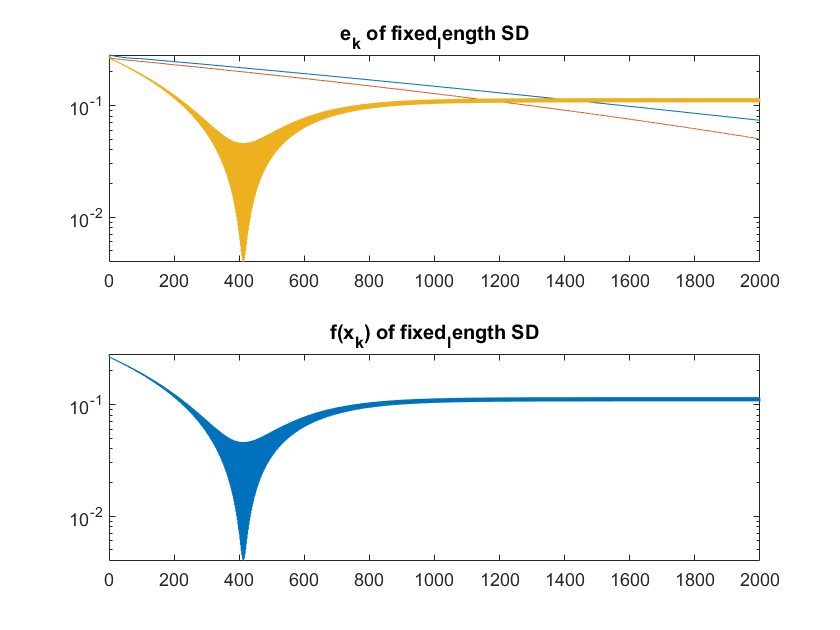

[f, df, ddf] = rosenbrock([1;1])